sympref('MatrixWithSquareBrackets',true);
sympref('AbbreviateOutput',false);
cdir = pwd;
[~,idx] = regexp(cdir,'PhD');
tdir = '\Code\TrajGen\Roads';
if string(cdir(idx + 1:end)) ~= string(tdir)
    cd([cdir(1:idx),tdir]);
end
close('all'); clear; clc;

C = StraightSegment(50,100);
C.Rotate(-20)
disp(C);

  StraightSegment with properties:

         Data: [3×100 double]
       Length: 50
      Heading: [-20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 -20 … ]
    Curvature: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 … ]
    Direction: []



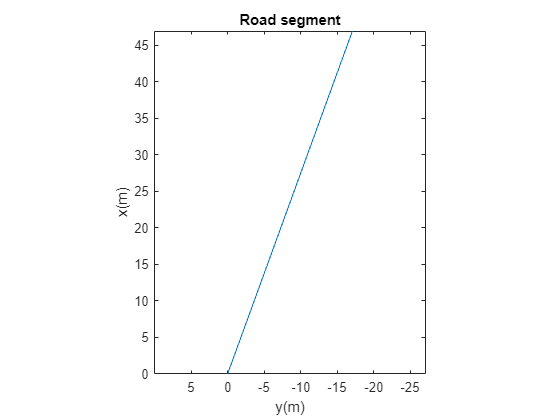

C.Plot()

r = 150;
ang_a = deg2rad(20);
C = ArcSegment(ang_a*r,r,"Left",100);
C.Rotate(0);
disp(C);

  ArcSegment with properties:

       Radius: 150
        Angle: 20
         Data: [3×100 double]
       Length: 52.3599
      Heading: [0 0.2020 0.4040 0.6061 0.8081 1.0101 1.2121 1.4141 1.6162 1.8182 2.0202 2.2222 2.4242 2.6263 2.8283 3.0303 3.2323 3.4343 3.6364 3.8384 … ]
    Curvature: [0.0067 0.0067 0.0067 0.0067 0.0067 0.0067 0.0067 0.0067 0.0067 0.0067 0.0067 0.0067 0.0067 0.0067 0.0067 0.0067 0.0067 0.0067 0.0067 … ]
    Direction: "Left"



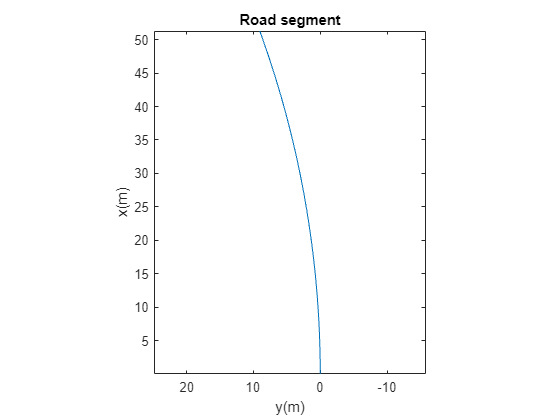

C.Plot();

C = ClothoidSegment(40,16,inf,"Right",100);
disp(C);

  ClothoidSegment with properties:

    StartRadius: 16
      EndRadius: Inf
           Data: [3×100 double]
         Length: 40
        Heading: [0 -0.0073 -0.0292 -0.0658 -0.1169 -0.1827 -0.2631 -0.3581 -0.4677 -0.5919 -0.7307 -0.8842 -1.0523 -1.2349 -1.4322 -1.6442 -1.8707 … ]
      Curvature: [0.0625 0.0619 0.0612 0.0606 0.0600 0.0593 0.0587 0.0581 0.0574 0.0568 0.0562 0.0556 0.0549 0.0543 0.0537 0.0530 0.0524 0.0518 0.0511 … ]
      Direction: "Right"



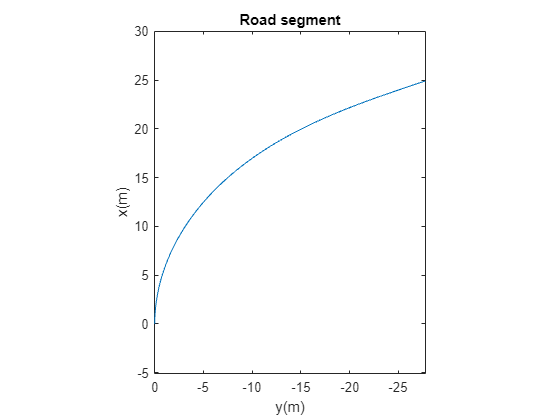

C.Plot();

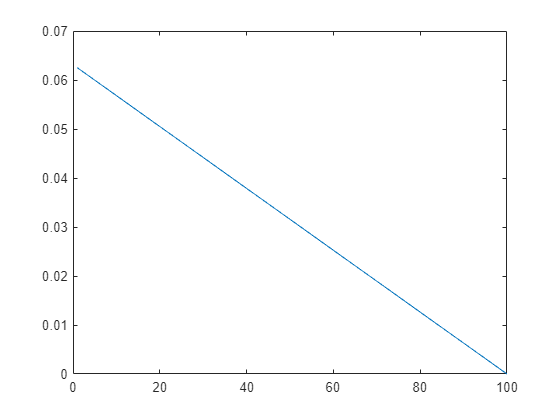

figure();
plot(C.Curvature);

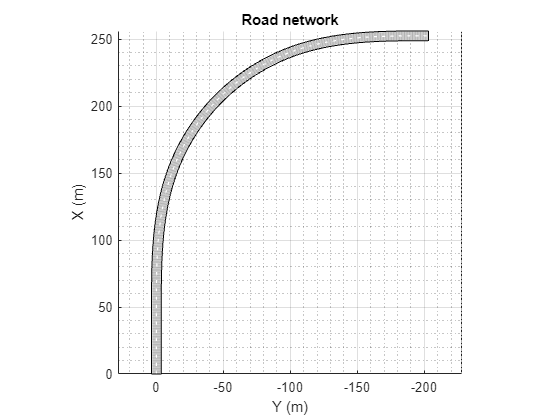

R = Road(1/4);
ra = 150;
ang = deg2rad(52);
R.AddStraightSegment(50);
R.AddClothoidSegment(100,inf,ra,"Right");
R.AddArcSegment(ra*ang,ra,"Right");
R.AddClothoidSegment(100,ra,inf,"Right");
% R.AddStraightSegment(50);
R.Show();

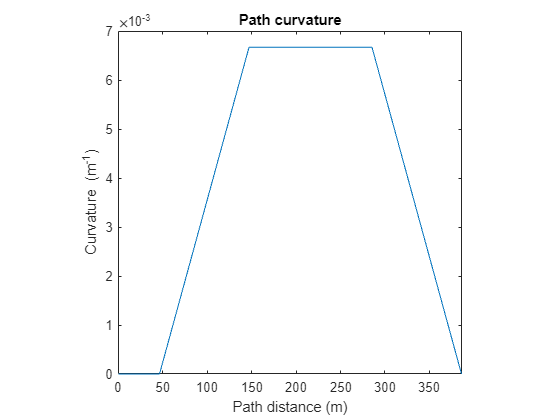

figure();
Distance = linspace(0,R.Length,length(R.Curvature));
plot(Distance,R.Curvature);
xlim([0,R.Length]);
xlabel('Path distance (m)');
ylabel('Curvature (m^{-1})');
title('Path curvature');
axis('square');